% s_simulateBroadband
%
% Simulate an LFP time series and then analyze it using our broadband
% extraction method. 
%
% SIMULATION: We simulate the LFP time series in 3 steps: 
% [1] There is an underlying, noiseless time series, which can be thought 
% of as the idealized rate of spike arrivals per neuron. 
% [2] We generate noisy samples scaled to this rate, which can be thought 
% of as a poisson-like nonlinearity defining the spike arrivals. 
% [3] We temporally integrate the noisy time series, which can be thought 
% of as the dendritic integration of the currents arising from spike arrivals.
%
% ANALYSIS: After generating multiple noisy time series with the
% identical underlying time-varying rate, we analyze the time series by
% extracting the broadband envelope in each trial using one of several
% algorithms [4]. We then average the envelopes across trials computed by each
% algorithm, and compare these time-varying broadband envelopes to the
% noiseless time-varying rate used to seed the time series [5].

## SIMULATION %%

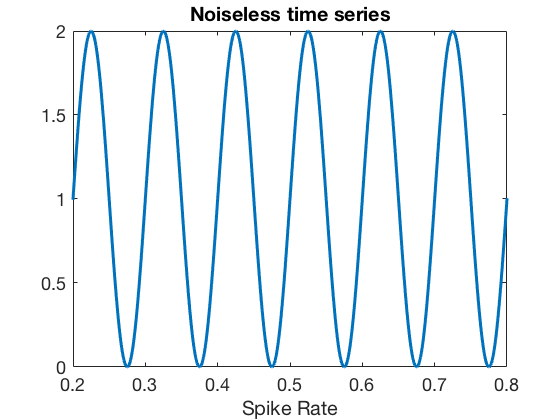

% Choose the reponse profile and integration method; add noise (optional)
params = [];

% Set parameters for the noiseless, time-varying rate 
params.simulation.resp        = 'sine';               % response profile: choose from {'boxcar' 'steps' 'step' 'pulse' 'bump' 'square' 'sine' 'noise' 'pred dn'} ([default = step];
params.simulation.t           = (-1999.5:1999.5)';       % trial length: trials are -2 to 2 seconds, and later clipped to [0 1] to avoid edge artifacts
params.simulation.srate       = 1000;                    % sample rate (Hz) (Q shouldn't this go with the noisy sampling part? or would that be redundant)
params.simulation.opt.f       = 10;                      % temporal frequency of response profile, applicable to sine wave or square wave

% Set parameters for noisy samples
params.simulation.n           = 100;                     % number of repeated trials
params.simulation.seed        = 1;                       % use same number to compare simulations for same random generator of samples; leave empty to use new generator every time

% Set parameters for leaky integration
params.simulation.alpha       = 0.1;                     % time constant for dendritic leakage
params.simulation.tau         = 0.0023;                  % time constant for post-synaptic current

% Set parameters for noise
params.simulation.amplnoise   = 0.01;                    % amplifier noise: scale factor of signal variance (if 0, no noise is added)

% Set parameters for plotting
params.plot.on     = 'yes';                              % yes/no
params.plot.fontsz = 18;                                 % font size
params.plot.lnwdth = 3;                                  % line width    

% [1] SIMULATE NOISELESS TIME SERIES

[spikeRate, params] = generateNoiselessTimeCourse(params);

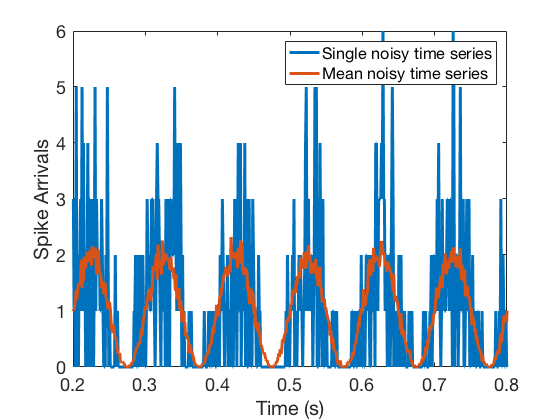


% [2] GENERATE NOISY SAMPLES

[spikeArrivals, params] = generateNoisySampledTimeCourses(spikeRate, params);

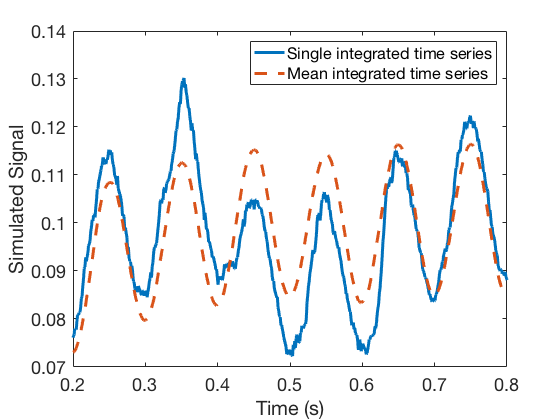


% [3] TEMPORALLY INTEGRATE

[simulatedSignal] = generateIntegratedTimeSeries(spikeArrivals, params);

## ANALYSIS %%

% This is an example analysis of ONE type of broadband computation

% [4] COMPUTE BROADBAND

% Define frequency bands and method for extracting broadband
params.analysis.bands            = {[50 70], 10};        % {[lower bound,  upper bound], window sz}
params.analysis.averagebandshow  = 'geomean';             % geomean/mean
params.analysis.averagebandswhen = 'after hilbert';       % 'before hilbert'/'after hilbert'
params.analysis.whitenbands      = 'yes';                 % yes/no
params.analysis.measure          = 'power';   % amplitude/power/logpower/logpower normalized (dora)

[estimatedBroadband, params] = extractBroadband(simulatedSignal, params);

% [5] COMPARE WITH INPUT

[out] = evaluateBroadband(spikeRate, estimatedBroadband, params); 

disp(out.regress.rsq);

      0.86675



disp(out.regress.sse);

       66.623



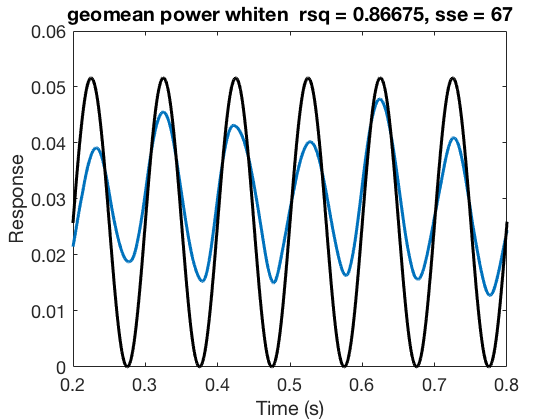

ti = get(gca, 'Title');
title([ti.String ' rsq = ' num2str(out.regress.rsq) ', sse = ' num2str(round(out.regress.sse))]);


% TO DO: develop more quantification metrics (now still empty)

% Impression from just playing around with parameters: 
% * Averaging bands after broadband computation = preferred (less noisy time course)
% * Mean power across bands higher R2/lower sse compared to amplitude and log power 
% * Geomean leads to slightly higher r2 but does not work with logpower, due to negative values
% * Whitening doesn't improve results

% Q: Why is logpower doing so bad without noise (and better with noise)?
% Perhaps not implemented correctly? (cf Dora method)

## %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

## SYSTEMATIC COMPARISONS OF SIMULATIONS / ANALYSES %%

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

## Question 1: amplitude vs. power vs log power

How does the quality of broadband estimate vary using amplitude, power or log power estimates? Prediction: Power best quality --> vary params.method

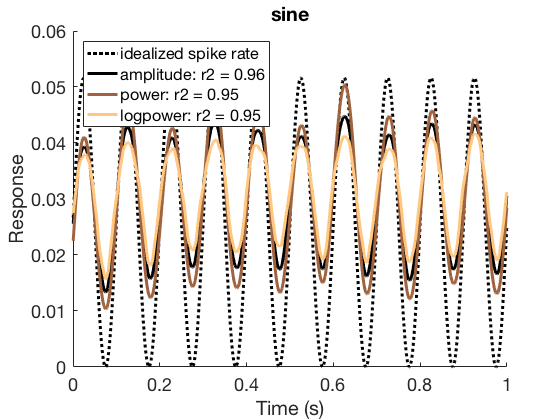

params.plot.on = 'no'; % suppress plotting each individual analysis; plot results together in one plot instead 
params.plot.xl = [0 1];

params.analysis.bands            = {[50 200], 10};     % {[lower bound,  upper bound], window sz}
params.analysis.averagebandshow  = 'mean';             % geomean/mean
params.analysis.averagebandswhen = 'after hilbert';    % 'before hilbert'/'after hilbert'
params.analysis.whitenbands      = 'no';               % yes/no

powerMeasures = {'amplitude', 'power', 'logpower'};
colors = copper(length(powerMeasures));

% CALC
bb = []; stats = [];
for ii = 1:length(powerMeasures)
    params.analysis.measure = powerMeasures{ii};          
    [bb{ii}, params] = extractBroadband(simulatedSignal, params);
    [stats{ii}] = evaluateBroadband(spikeRate, bb{ii}, params); 
end

% PLOT
fH = figure;  set(fH, 'Color', 'w'); hold on;
labels = [];

t = params.simulation.t/params.simulation.srate;
% Clip time series to avoid edge artifacts
idx = t > 0 & t < 1;

% Plot spikeRate
spikeRateToPlot = spikeRate(idx) / norm(spikeRate(idx));
plot(t(idx), spikeRateToPlot, 'k:', 'LineWidth', params.plot.lnwdth)
labels{1} = 'idealized spike rate';

for ii = 1:length(powerMeasures)
    
    meanBroadband = mean(bb{ii},2);
    
    % Subtract 'prestim' baseline
    baseline = meanBroadband(t > -1 & t < 0);
    meanBroadband = meanBroadband(idx) - mean(baseline);

    % Scale for plotting
    mnToPlot = meanBroadband / norm(meanBroadband);
    
    plot(t(idx), mnToPlot, 'Color', colors(ii,:), 'LineWidth', params.plot.lnwdth)
    set(gca, 'XLim', params.plot.xl);
    set(gca, 'FontSize', params.plot.fontsz, 'XLim', params.plot.xl)
    xlabel('Time (s)')
    ylabel('Response')
    labels{ii+1} = [powerMeasures{ii} ': r2 = ' num2str(round(stats{ii}.regress.rsq,2))];
end
legend(labels, 'Location', 'NorthWest');
title(params.simulation.resp);

## Question 2: temporal precision

% How is temporal precision of broadband estimate affected by analysis parameters? 
% Prediction: Time series containing sharp transients need wide bands (more time precision)
% --> vary params.resp / params.bands, where is the optimum?

params.plot.on = 'no'; % suppress plotting each individual analysis; plot results together in one plot instead 

params.analysis.averagebandshow  = 'mean';             % geomean/mean
params.analysis.averagebandswhen = 'after hilbert';    % 'before hilbert'/'after hilbert'
params.analysis.whitenbands      = 'no';               % yes/no
params.analysis.measure          = 'power';    

% CALC: bandwidths
windowSizes = {1, 5, 10, 25, 50};
colors = jet(length(windowSizes));

bb = []; stats = [];
for ii = 1:length(windowSizes)
    params.analysis.bands  = {[50 200], windowSizes{ii}};     % {[lower bound,  upper bound], window sz}   
    [bb{ii}, params] = extractBroadband(simulatedSignal, params);
    [stats{ii}] = evaluateBroadband(spikeRate, bb{ii}, params); 
end

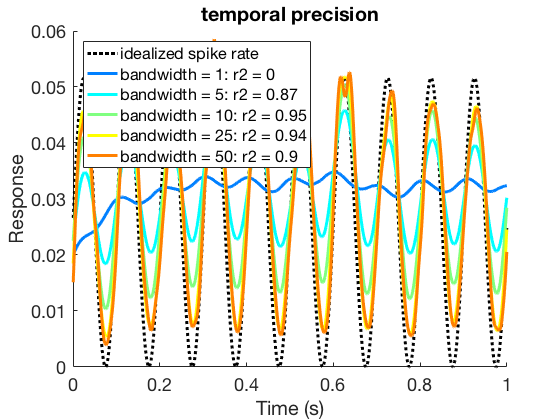


% PLOT
fH = figure;  set(fH, 'Color', 'w'); hold on;
labels = [];

t = params.simulation.t/params.simulation.srate;
% Clip time series to avoid edge artifacts
idx = t > 0 & t < 1;

% Plot spikeRate
spikeRateToPlot = spikeRate(idx) / norm(spikeRate(idx));
plot(t(idx), spikeRateToPlot, 'k:', 'LineWidth', params.plot.lnwdth)
labels{1} = 'idealized spike rate';

for ii = 1:length(windowSizes)
    
    meanBroadband = mean(bb{ii},2);
    
    % Subtract 'prestim' baseline
    baseline = meanBroadband(t > -1 & t < 0);
    meanBroadband = meanBroadband(idx) - mean(baseline);

    % Scale for plotting
    mnToPlot = meanBroadband / norm(meanBroadband);
    
    plot(t(idx), mnToPlot, 'Color', colors(ii,:), 'LineWidth', params.plot.lnwdth)
    set(gca, 'XLim', params.plot.xl);
    set(gca, 'FontSize', params.plot.fontsz, 'XLim', params.plot.xl)
    xlabel('Time (s)')
    ylabel('Response')
    labels{ii+1} = ['bandwidth = ' num2str(windowSizes{ii}) ': r2 = ' num2str(round(stats{ii}.regress.rsq,2))];
end
legend(labels, 'Location', 'NorthWest');
title('temporal precision');


% CALC: lower bounds
lowerBounds = {20, 40, 60, 80, 100};
colors = jet(length(windowSizes));

bb = []; stats = [];
for ii = 1:length(lowerBounds)
    params.analysis.bands  = {[lowerBounds{ii} 200], 10};     % {[lower bound,  upper bound], window sz}   
    [bb{ii}, params] = extractBroadband(simulatedSignal, params);
    [stats{ii}] = evaluateBroadband(spikeRate, bb{ii}, params); 
end

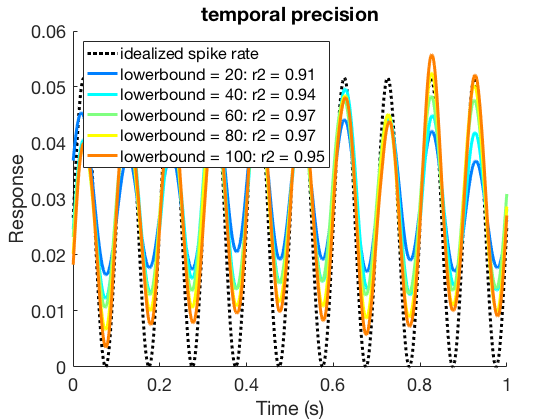


% PLOT
fH = figure;  set(fH, 'Color', 'w'); hold on;
labels = [];

t = params.simulation.t/params.simulation.srate;
% Clip time series to avoid edge artifacts
idx = t > 0 & t < 1;

% Plot spikeRate
spikeRateToPlot = spikeRate(idx) / norm(spikeRate(idx));
plot(t(idx), spikeRateToPlot, 'k:', 'LineWidth', params.plot.lnwdth)
labels{1} = 'idealized spike rate';

for ii = 1:length(lowerBounds)
    
    meanBroadband = mean(bb{ii},2);
    
    % Subtract 'prestim' baseline
    baseline = meanBroadband(t > -1 & t < 0);
    meanBroadband = meanBroadband(idx) - mean(baseline);

    % Scale for plotting
    mnToPlot = meanBroadband / norm(meanBroadband);
    
    plot(t(idx), mnToPlot, 'Color', colors(ii,:), 'LineWidth', params.plot.lnwdth)
    set(gca, 'XLim', params.plot.xl);
    set(gca, 'FontSize', params.plot.fontsz, 'XLim', params.plot.xl)
    xlabel('Time (s)')
    ylabel('Response')
    labels{ii+1} = ['lowerbound = ' num2str(lowerBounds{ii}) ': r2 = ' num2str(round(stats{ii}.regress.rsq,2))];
end
legend(labels, 'Location', 'NorthWest');
title('temporal precision');

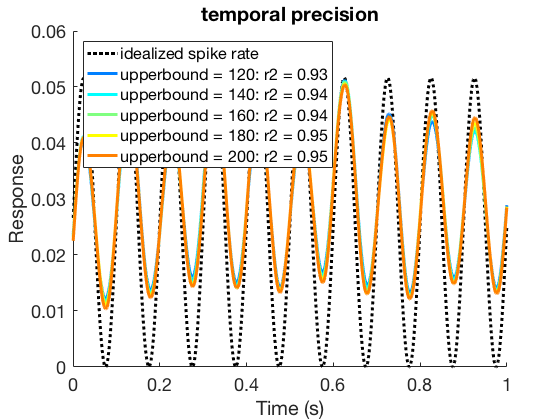


% CALC: lower bounds
upperBounds = {120, 140, 160, 180, 200};
colors = jet(length(windowSizes));

bb = []; stats = [];
for ii = 1:length(lowerBounds)
    params.analysis.bands  = {[50 upperBounds{ii}], 10};     % {[lower bound,  upper bound], window sz}   
    [bb{ii}, params] = extractBroadband(simulatedSignal, params);
    [stats{ii}] = evaluateBroadband(spikeRate, bb{ii}, params); 
end

% PLOT
fH = figure;  set(fH, 'Color', 'w'); hold on;
labels = [];

t = params.simulation.t/params.simulation.srate;
% Clip time series to avoid edge artifacts
idx = t > 0 & t < 1;

% Plot spikeRate
spikeRateToPlot = spikeRate(idx) / norm(spikeRate(idx));
plot(t(idx), spikeRateToPlot, 'k:', 'LineWidth', params.plot.lnwdth)
labels{1} = 'idealized spike rate';

for ii = 1:length(upperBounds)
    
    meanBroadband = mean(bb{ii},2);
    
    % Subtract 'prestim' baseline
    baseline = meanBroadband(t > -1 & t < 0);
    meanBroadband = meanBroadband(idx) - mean(baseline);

    % Scale for plotting
    mnToPlot = meanBroadband / norm(meanBroadband);
    
    plot(t(idx), mnToPlot, 'Color', colors(ii,:), 'LineWidth', params.plot.lnwdth)
    set(gca, 'XLim', params.plot.xl);
    set(gca, 'FontSize', params.plot.fontsz, 'XLim', params.plot.xl)
    xlabel('Time (s)')
    ylabel('Response')
    labels{ii+1} = ['upperbound = ' num2str(upperBounds{ii}) ': r2 = ' num2str(round(stats{ii}.regress.rsq,2))];
end
legend(labels, 'Location', 'NorthWest');
title('temporal precision');

## Question 3: Amplifier noise

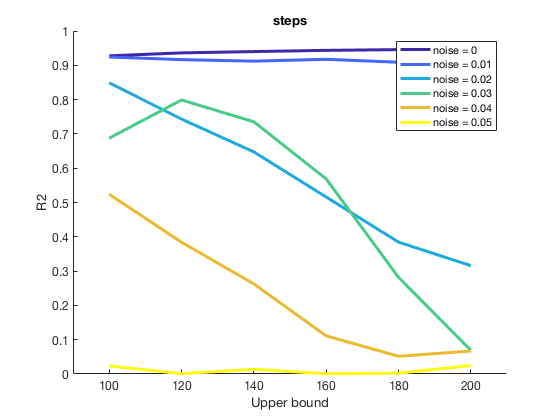

% How is the quality of the broadband estimate affected by amplifier noise
% Prediction: Quality decreases for high bands under conditions of high noise
% --> vary params.amplnoise / params.bands, where is the optimum?
clear all;

% Choose the reponse profile and integration method; add noise (optional)
params = [];

% Set parameters for the noiseless, time-varying rate 
params.simulation.resp        = 'steps';               % response profile: choose from {'boxcar' 'steps' 'step' 'pulse' 'bump' 'square' 'sine' 'noise' 'pred dn'} ([default = step];
params.simulation.t           = (-1999.5:1999.5)';       % trial length: trials are -2 to 2 seconds, and later clipped to [0 1] to avoid edge artifacts
params.simulation.srate       = 1000;                    % sample rate (Hz) (Q shouldn't this go with the noisy sampling part? or would that be redundant)

% Set parameters for noisy samples
params.simulation.n           = 100;                     % number of repeated trials
params.simulation.seed        = 1;%[];                       % use same number to compare simulations for same random generator of samples; leave empty to use new generator every time

% Set parameters for leaky integration
params.simulation.alpha       = 0.1;       % time constant for dendritic leakage
params.simulation.tau         = 0.0023;    % time constant for post-synaptic current

% Set parameters for plotting
params.plot.on     = 'no';
params.plot.fontsz = 12; % font size
params.plot.lnwdth = 3;  % line width    

% Define frequency bands and method for extracting broadband
params.analysis.averagebandshow  = 'mean';             % geomean/mean
params.analysis.averagebandswhen = 'after hilbert';    % 'before hilbert'/'after hilbert'
params.analysis.whitenbands      = 'no';               % yes/no
params.analysis.measure          = 'power';            % amplitude/power/logpower

[spikeRate, params] = generateNoiselessTimeCourse(params);
[spikeArrivals, params] = generateNoisySampledTimeCourses(spikeRate, params);

% GENERATE DIFFERENT NOISE REGIMES
noiseLevels = [0 0.01 0.02 0.03 0.04 0.05];
colors = parula(length(noiseLevels));

% COMPARE UPPER BOUNDS
upperBounds = [100 120 140 160 180 200];

bb = [];
stats = [];
for ii = 1:length(noiseLevels)
    params.simulation.amplnoise = noiseLevels(ii);      
    [simulatedSignal] = generateIntegratedTimeSeries(spikeArrivals, params);
    for jj = 1:length(upperBounds)
        params.analysis.bands = {[50 upperBounds(jj)], 10};     
        [bb{ii,jj}, params] = extractBroadband(simulatedSignal, params);
        [stats{ii,jj}] = evaluateBroadband(spikeRate, bb{ii,jj}, params); 
    end
end

% PLOT
rsqToPlot = [];
labels = [];
for ii = 1:length(noiseLevels)
    for jj = 1:length(upperBounds)
        rsqToPlot(ii,jj) = stats{ii,jj}.regress.rsq;
        labels{ii} = ['noise = ' num2str(noiseLevels(ii))];
    end
end
 
fH = figure;  set(fH, 'Color', 'w'); hold on;
for ii = 1:length(noiseLevels)
    plot(upperBounds, rsqToPlot(ii,:), 'Color', colors(ii,:), 'LineWidth', params.plot.lnwdth);
end
set(gca, 'FontSize', params.plot.fontsz)
set(gca, 'XLim', [min(upperBounds)-10 max(upperBounds)+10], 'YLim', [0 1])
xlabel('Upper bound')
ylabel('R2')
legend(labels);    
title(params.simulation.resp);

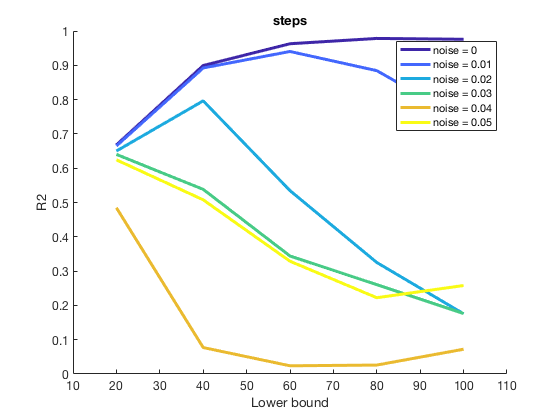


% COMPARE LOWER BOUNDS
lowerBounds = [20 40 60 80 100];

bb = [];
stats = [];
for ii = 1:length(noiseLevels)
    params.simulation.amplnoise = noiseLevels(ii);      
    [simulatedSignal] = generateIntegratedTimeSeries(spikeArrivals, params);
    for jj = 1:length(lowerBounds)
        params.analysis.bands = {[lowerBounds(jj) 150], 10};     
        [bb{ii,jj}, params] = extractBroadband(simulatedSignal, params);
        [stats{ii,jj}] = evaluateBroadband(spikeRate, bb{ii,jj}, params); 
    end
end

% PLOT
rsqToPlot = [];
labels = [];
for ii = 1:length(noiseLevels)
    for jj = 1:length(lowerBounds)
        rsqToPlot(ii,jj) = stats{ii,jj}.regress.rsq;
        labels{ii} = ['noise = ' num2str(noiseLevels(ii))];
    end
end
 
fH = figure;  set(fH, 'Color', 'w'); hold on;
for ii = 1:length(noiseLevels)
    plot(lowerBounds, rsqToPlot(ii,:), 'Color', colors(ii,:), 'LineWidth', params.plot.lnwdth);
end
set(gca, 'FontSize', params.plot.fontsz)
set(gca, 'XLim', [min(lowerBounds)-10 max(lowerBounds)+10], 'YLim', [0 1])
xlabel('Lower bound')
ylabel('R2')
legend(labels);    
title(params.simulation.resp);

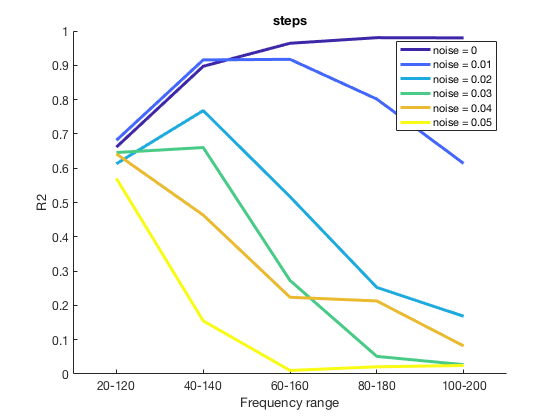


% COMPARE RANGES
lowerBounds = [20 40 60 80 100]; % will add 100 for upper bound

bb = [];
stats = [];
for ii = 1:length(noiseLevels)
    params.simulation.amplnoise = noiseLevels(ii);      
    [simulatedSignal] = generateIntegratedTimeSeries(spikeArrivals, params);
    for jj = 1:length(lowerBounds)
        params.analysis.bands = {[lowerBounds(jj) lowerBounds(jj)+100], 10};     
        [bb{ii,jj}, params] = extractBroadband(simulatedSignal, params);
        [stats{ii,jj}] = evaluateBroadband(spikeRate, bb{ii,jj}, params); 
    end
end

% PLOT
rsqToPlot = [];
labels = [];
for ii = 1:length(noiseLevels)
    for jj = 1:length(lowerBounds)
        rsqToPlot(ii,jj) = stats{ii,jj}.regress.rsq;
        labels{ii} = ['noise = ' num2str(noiseLevels(ii))];
    end
end
 
fH = figure;  set(fH, 'Color', 'w'); hold on;
for ii = 1:length(noiseLevels)
    plot(lowerBounds, rsqToPlot(ii,:), 'Color', colors(ii,:), 'LineWidth', params.plot.lnwdth);
end
set(gca, 'FontSize', params.plot.fontsz)
xnames = [];
for jj = 1:length(lowerBounds)
    xnames{jj} = [num2str(lowerBounds(jj)) '-' num2str(lowerBounds(jj)+100)];
end
set(gca, 'XTick', [min(lowerBounds):20:max(lowerBounds)], 'XTickLabel', xnames)
set(gca, 'XLim', [min(lowerBounds)-10 max(lowerBounds)+10], 'YLim', [0 1])
xlabel('Frequency range')
ylabel('R2')
legend(labels);    
title(params.simulation.resp);

## Implications for REAL data analysis:

% Given assumptions XY, e.g. amplitude vs power, will affect interpretation
% of selectivity (e.g. face response 2x or 4x as high as house response)
% How well can we capture actual transients in the data?
% What are the BIG effects of choices made in analysis?